imr = imread('kvarn.tif');
imr = double(imr)/255;

% 1.1

b11 = (imr >= 0.5);
imwrite(b11, 'b11.tif', 'Resolution', 150);

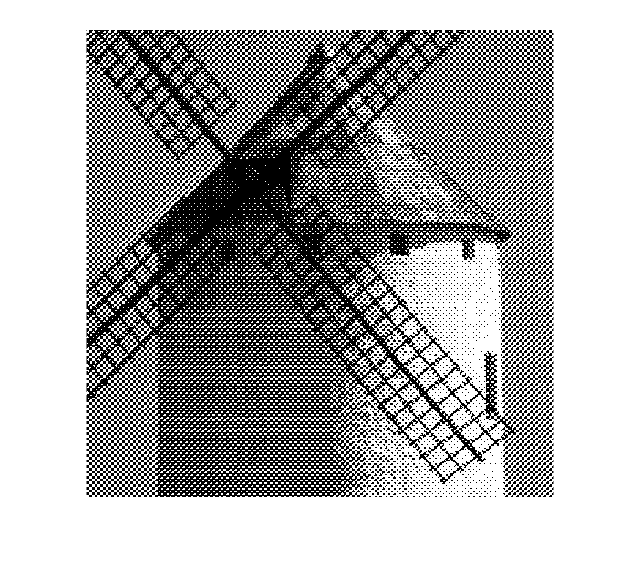

%1.2
load('troskelmatriser.mat')

tr1_norm = tr1/ 19; %Fråga Sasan 
tr2_norm = tr2/ 33; 

imr_tr1 = troskel(imr, tr1_norm);
imr_tr2 = troskel(imr, tr2_norm);

imshow(imr_tr1)

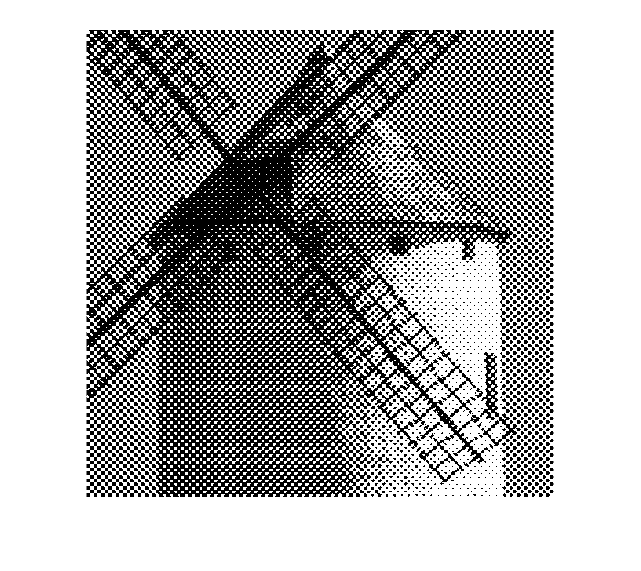

imshow(imr_tr2)


imwrite(imr_tr1, 'b12_tr1.tif','Resolution', 150);
imwrite(imr_tr2, 'b12_tr2.tif','Resolution', 150);

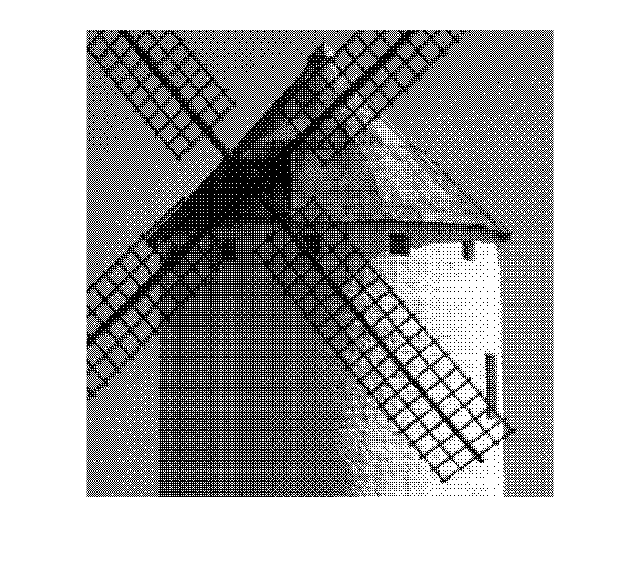

% 1.3

tr3_norm = tr3/ 33; 

imr_tr3 = troskel(imr, tr3_norm);
imshow(imr_tr3)

imwrite(imr_tr3, 'b13.tif','Resolution', 150);

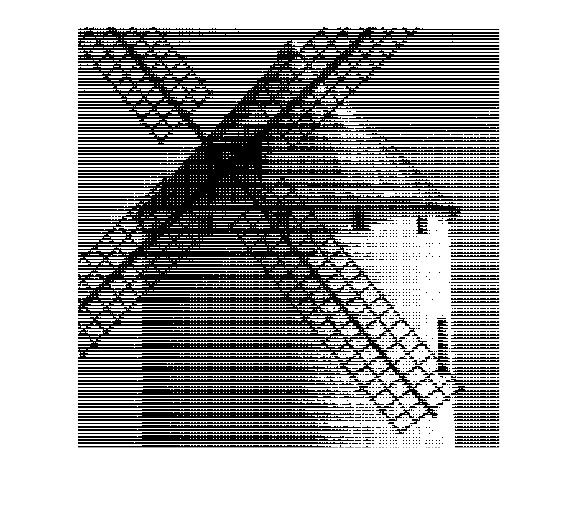

% 1.4

linjeraster = [1 2 3 4; 5 6 7 8; 9 10 11 12; 13 14 15 16] / 17;
spiralraster = [1 2 3 4; 12 13 14 5; 11 16 15 6; 10 9 8 7] / 17;  

b14_linj = troskel(imr, linjeraster);
b14_spiral = troskel(imr, spiralraster);

imshow(b14_linj)

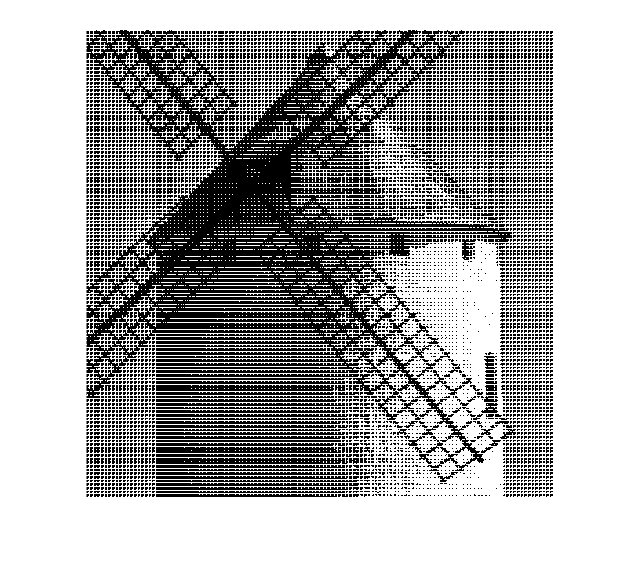

imshow(b14_spiral)


imwrite(b14_linj, 'b14_linj.tif','Resolution', 150);
imwrite(b14_spiral, 'b14_spiral.tif','Resolution', 150);

% 2.1
imwrite(tabellrast(imr), 'b21.tif','Resolution', 150);

ans = 25

% 2.2
imwrite(tabellrast2(imr), 'b22.tif','Resolution', 150);

% 2.4
imwrite(tabellrast3(imr), 'b24.tif','Resolution', 150);

% 3.1

felspr1 = [0 0 7/16; 
          3/16 5/16 1/16];

imwrite(errordif(imr, felspr1), 'b31.tif','Resolution', 150);

% 3.2

felspr2 = [
    0 0 0 7 5;
    3 5 7 5 3;
    1 3 5 3 1
    ] * (1/48);

imwrite(errordif(imr, felspr2), 'b32.tif','Resolution', 150);


% 3.4

felspr3 = [
    0 0 1
    0 0 0
    ];

imwrite(errordif(imr, felspr3), 'b34a.tif','Resolution', 150);

felspr4 = [
    0 0 2
    0 8 0
   ] * (1/10);

imwrite(errordif(imr, felspr4), 'b34b.tif','Resolution', 150);

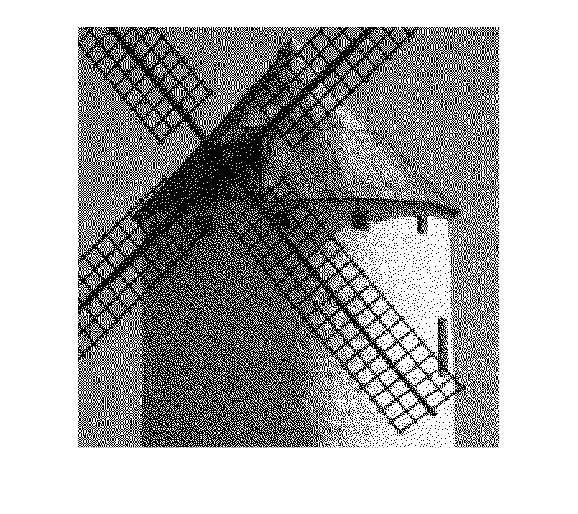

% 3.6

brus = (rand(512) - 0.5) * 0.2;

imr_brus = imr + brus;

imshow(errordif(imr_brus, felspr1))


imwrite(errordif(imr_brus, felspr1), 'b36.tif','Resolution', 150);

% 4.0

imwrite(imcdp(imr), 'b40.tif','Resolution', 150);

imcdp
----------
here13
here14
here14
9% done
----
17% done
----
26% done
----
34% done
----
43% done
----
52% done
----
60% done
----
69% done
----
78% done
----
86% done
----
95% done
----
here9
here10
here18
here8
here6
here17
here7
here5
here3
here4
here16
here11
here2
here12
here15
here1


% 5.1

help mysnr

  out=mysnr(in, noise);
 
  in is the original image
  noise is the difference between the original image and the reproduction
  (i.e. the halftoned image)
  out returns the SNR




snr1 = mysnr(imr, imr - b11);
snr2 = mysnr(imr, imr - errordif(imr, felspr1));
snr3 = mysnr(imr, imr - imcdp(imr) );

imcdp
----------
here13
here14
here14
9% done
----
17% done
----
26% done
----
34% done
----
43% done
----
52% done
----
60% done
----
69% done
----
78% done
----
86% done
----
95% done
----
here9
here15
here10
here8
here6
here17
here18
here7
here5
here4
here1
here3
here11
here16
here2
here12



snr1

snr1 = 2.5915

snr2

snr2 = 0.8801

snr3

snr3 = 0.8075

% 5.2 
help snr_filter

    R = SNR(X, Y) computes the signal to noise ratio (SNR) in dB.
    The signal X and the noise Y are first filtered by a filter
    representing the eye.




e = snr_filter(imr, imr - b11);
t = snr_filter(imr, imr - errordif(imr, felspr1));
tr = snr_filter(imr, imr - imcdp(imr));

imcdp
----------
here13
here14
here14
9% done
----
17% done
----
26% done
----
34% done
----
43% done
----
52% done
----
60% done
----
69% done
----
78% done
----
86% done
----
95% done
----
here9
here10
here8
here17
here7
here6
here5
here4
here18
here16
here15
here11
here3
here2
here12
here1



e

e = 2.9988

t 

t = 13.9621

tr

tr = 12.0067

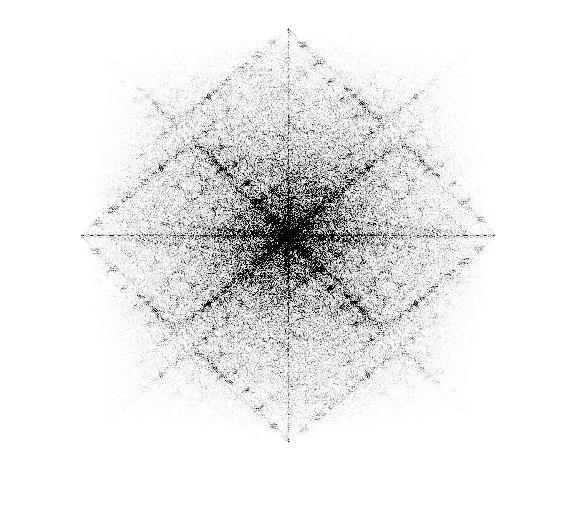

% 5.3
bruh = QNS(imr, b11);

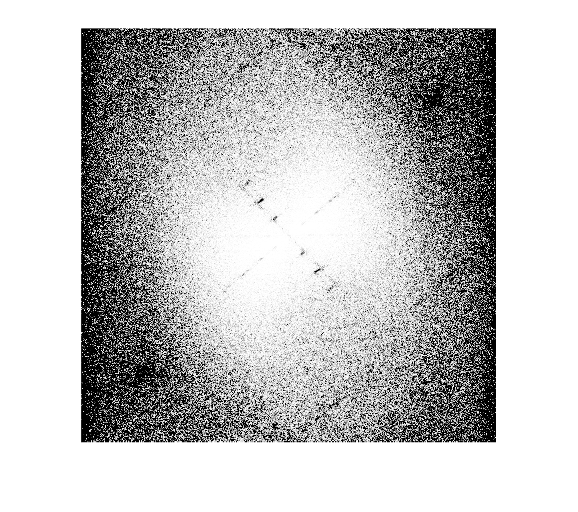

bruh2 = QNS(imr, errordif(imr, felspr1));

imcdp
----------
here13
here14
here14
9% done
----
17% done
----
26% done
----
34% done
----
43% done
----
52% done
----
52% done
----
60% done
----
69% done
----
78% done
----
86% done
----
here15
95% done
----
here9
here8
here10
here17
here7
here5
here6
here4
here18
here3
here16
here11
here2
here12
here1


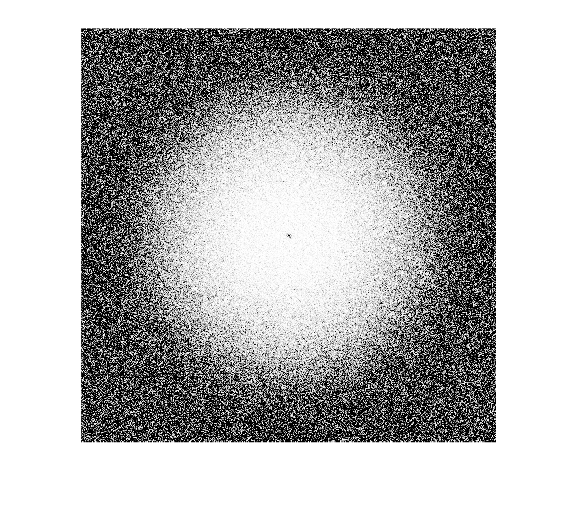

bruh3 = QNS(imr, imcdp(imr));



imwrite(bruh, 'QNS1.tif','Resolution', 150);
imwrite(bruh2, 'QNS2.tif','Resolution', 150);
imwrite(bruh3, 'QNS3.tif','Resolution', 150);

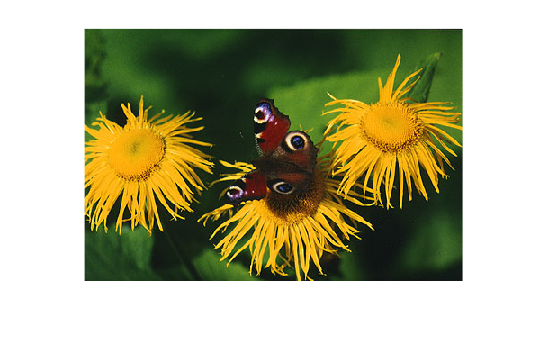

% del 3
musicians = im2double(imread('musicians.tif'));
butterfly = im2double(imread('butterfly.tif'));

imshow(butterfly)

imgButterfly = fargraster(butterfly, 'imcdp');

imcdp
----------
23% done
----
here14
47% done
----
here14
70% done
----
here13
here12
94% done
----
here11
here7
here9
here16
here8
here4
here5
here17
here2
here6
here3
here18
here10
here15
here1
imcdp
----------
here14
24% done
----
48% done
----
here14
here16
here12
72% done
----
72% done
----
here13
here15
here11
here18
96% done
----
here9
here10
here6
here8
here7
here1
here5
here4
here3
here17
here2
imcdp
----------
here15
here16
here2
here17
here4
here3
here14
here7
here6
here8
88% done
----
here9
here18
here14
here1
here10
here12
here13
here11
here5


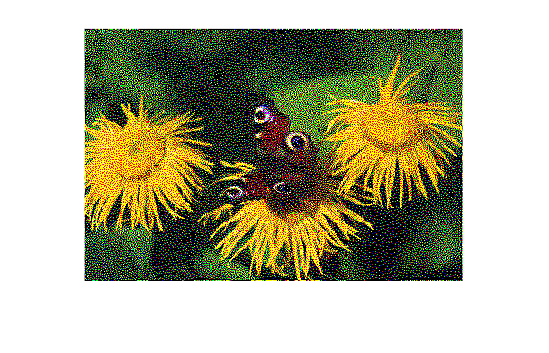

imshow(imgButterfly)

imgButterfly = fargraster(butterfly, 'sjjhdsb');

Skriv errordif eller imdcp


imgButterfly = fargraster(butterfly, 'imcdp');

imcdp
----------
23% done
----
47% done
----
here14
70% done
----
here14
here13
here12
94% done
----
here11
here4
here16
here9
here8
here7
here17
here6
here5
here18
here2
here15
here10
here3
here1
imcdp
----------
here14
24% done
----
48% done
----
here14
here12
72% done
----
here13
here11
here16
96% done
----
here10
here9
here6
here7
here8
here4
here3
here5
here1
here2
here17
here18
here15
imcdp
----------
here15
here16
here17
here3
here6
here4
here14
here8
88% done
----
here9
here7
here14
here2
here10
here12
here13
here11
here5
here18
here1


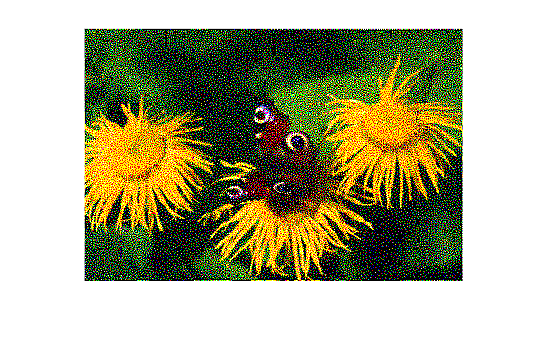

imshow(imgButterfly)

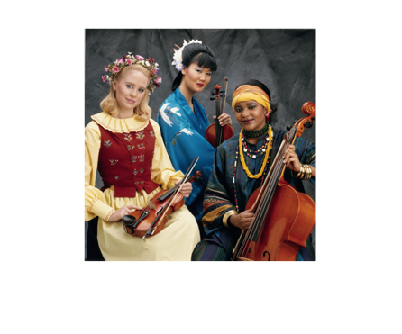


imshow(musicians)

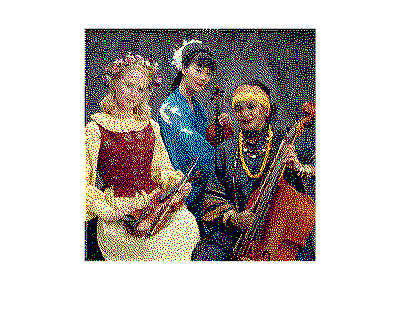

imgMusicians = fargraster(musicians, 'errordif');
imshow(imgMusicians)